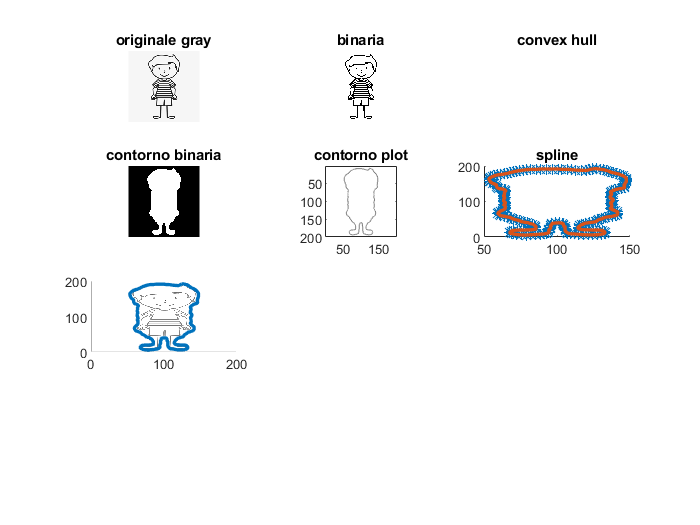

clear all
close all
[filename, filepath] = uigetfile({'*.jpg';'*.png';'*.bmp'}, "immagine da caricare"); %permette di selezionare solo file con le estensioni specificate
fullFileName = [filepath filename];
punti=200;
resolution=200;
grayImage =rgb2gray(imresize(imread(fullFileName),[resolution resolution]));

subplot(431)
imshow(grayImage)
title('originale gray')

subplot(432)
mask=imbinarize(grayImage);
imshow(mask)
title('binaria')

subplot(433)
mask = bwconvhull(mask, 'Union'); %genera convex hull dell'immagine
imshow(mask)
title('convex hull')

subplot(434)
bw = activecontour(grayImage, mask, 400, 'edge'); %crea immagine binaria del contorno usando il convex hull  
imshow(bw)
title('contorno binaria')

subplot(435)
[C,h]=imcontour(bw,1); %plotta il contorno dell'immagine 1 è il livello?!
title('contorno plot')
%hold on
%x=zeros(1,C(2,1));
%y=zeros(1,C(2,1));
j=1;
if punti>C(2,1)
    punti=C(2,1);
end
for i=linspace(2,C(2,1),punti)
    i=floor(i);
    x(j)=C(1,i);
    y(j)=C(2,i);
    j=j+1;
    %scatter(C(1,i),C(2,i),'*')
end
x(j)=x(1); %chiude la figura 
y(j)=y(1);

subplot(436)
hold on
scatter(x,resolution-y,'*') %plot punti usati
pp=cscvn([x;resolution-y]); %interpolazione dei punti della curva con spline cubica
fnplt(pp) %plot curva
title('spline')

subplot(437)
hold on
image(flipud(grayImage))
colormap gray
pp=cscvn([x;resolution-y]);
fnplt(pp)